# **demo14 of Im2mesh package**

demo14 - How to use polyshape object to define multi-part geometry for meshing

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Function poly2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Polyshape

Polyshape is a MATLAB built-in object for polygon-like shapes. We can use object functions of polyshape to create multi-part geometry. Please refer to the following webpage about object functions of polyshape.

[https://www.mathworks.com/help/matlab/ref/polyshape.html](https://www.mathworks.com/help/matlab/ref/polyshape.html)

Let's create a unit square.

vertex = [ 0 0; 1 0; 1 1; 0 1 ];
psUnitSq = polyshape(vertex);

Create three rods - A B C, and combine them using function union.

psRodBase = scale( psUnitSq, [1, 0.05]);

psRodA = rotate( psRodBase, 155 );
psRodA = translate( psRodA, [0.6 0.8] );
psRodB = translate( psRodBase, [0.1 0.9] );
psRodC = translate( psRodBase, [-0.1 0.5] );

psRodABC = union([ psRodA; psRodB; psRodC ]);

Create a circle.

t = 0.05:0.03:2*pi;
x1 = 0.8 + 0.15*cos(t);
y1 = 0.95 + 0.15*sin(t);
psCircle = polyshape(x1,y1);

Plot them together.

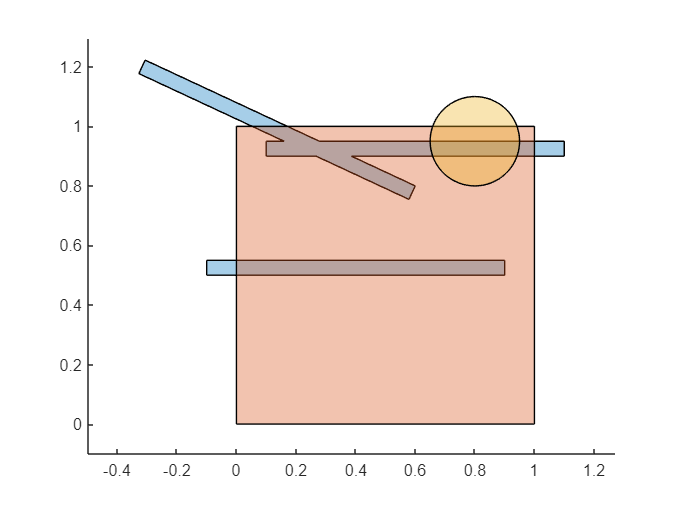

plot( [psRodABC; psUnitSq; psCircle] ); 
axis equal

We saw that they are overlapped.

## Boolean operations

We use boolean operations of polyshape object to remove overlapped regions.

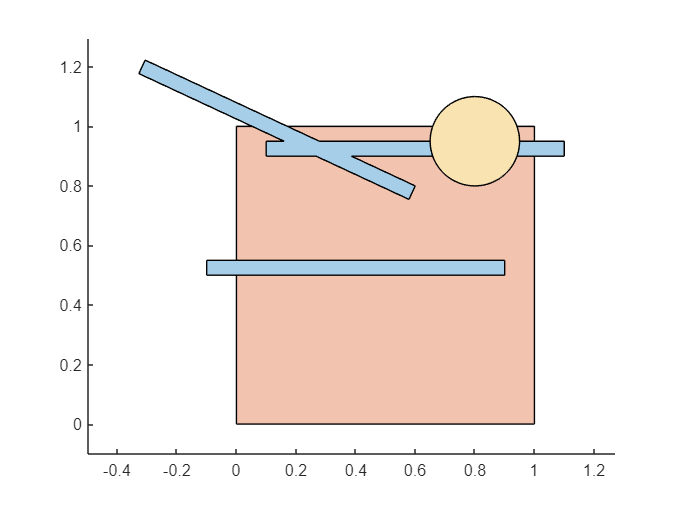

psBlock = subtract( psUnitSq, psRodABC );
psBlock = subtract( psBlock, psCircle );

psRodABC = subtract( psRodABC, psCircle );

plot( [psRodABC; psBlock; psCircle] ); 
axis equal

## Cell array of polyshape

We put them into a cell array - psCell. Each element in psCell represent different parts. It's like labelling.

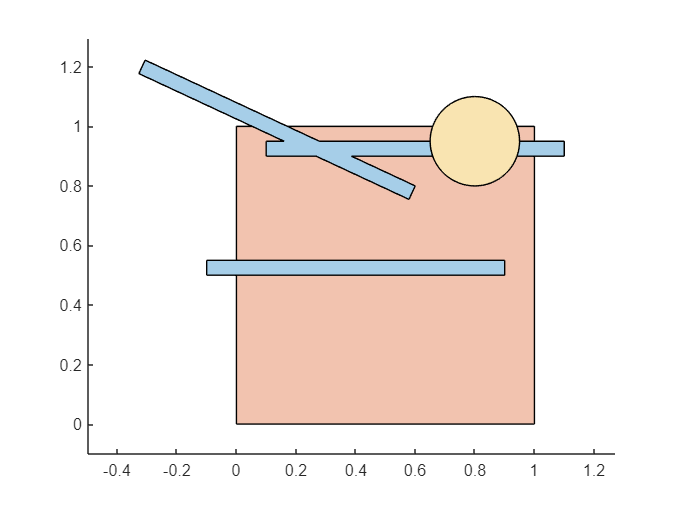

psCell = { psRodABC; psBlock; psCircle };

% plot psCell
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

## Add intersect points

Polyshape objects are not able to find intersect points automatically. Therefore, we convert the cell array of polyshape 'psCell' to a cell array of polygonal boundaries 'bounds', and use function addIntersectPnts to add intersect points to 'bounds'. 

Note that if we don't add intersect points, mesh generation will fail.

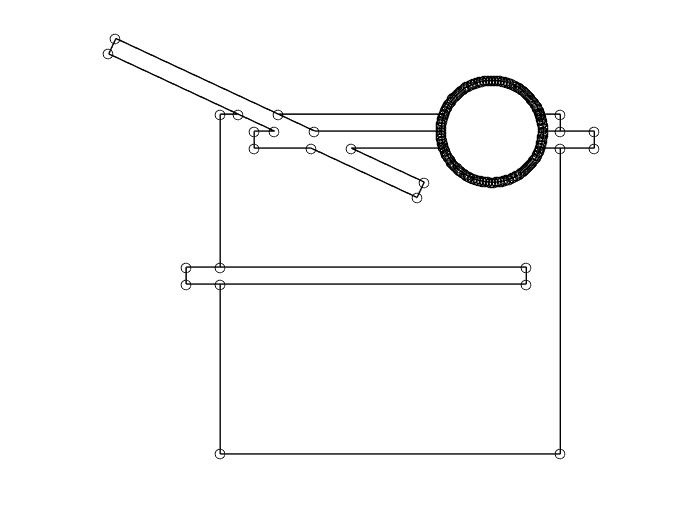

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;   % distance tolerance for intersect
boundsNew = addIntersectPnts( bounds, tol_intersect );

% plot boundaries and show all vertices
plotBounds(boundsNew,false,'ko-')

We saw that there are a lot of vertices on the circle.

## Simplify boundaries

We want to reduce the number of vertices on the circle.

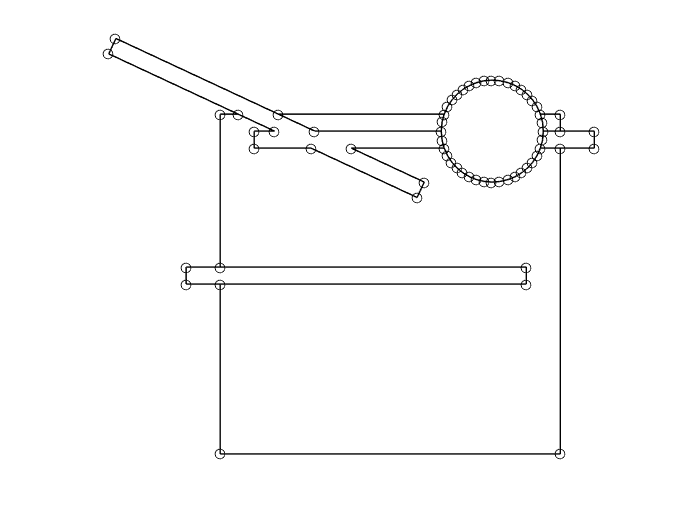

boundsCtrlP = getCtrlPnts( boundsNew, false );

tolerance = 0.001;  % for Douglas-Peucker polyline simplification
boundsSimplified = simplifyBounds( boundsCtrlP, tolerance, 0 );

% show all vertices
plotBounds(boundsSimplified,false,'ko-')

Wonderful! We saw that the number of vertices on the circle reduced a lot.

Note that you need to adjust the value of tolerance to achieve your desired reduction.

## Generate mesh

We use function poly2mesh to generate mesh. 

Function poly2mesh uses mesh generator [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda).

[ poly_node, poly_edge ] = getPolyNodeEdge( boundsSimplified );

hmax = 500; 
mesh_kind = 'delaunay';
grad_limit = 0.25;
[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                106                 97
         10                125                220
         14                127                270


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                171                 97
         10                191                614
         16                195                769


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                169                763
          8                  9                763



Plot mesh.

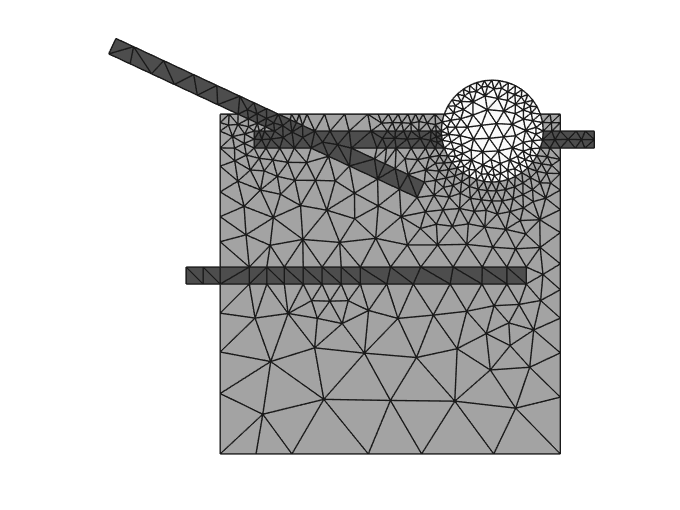

plotMeshes(vert,tria,tnum);

Wonderful!

We can also use MATLAB built-in function generateMesh or open-source software Gmsh to generate mesh for multi-part geometry. We have demonstrated how to do that in other examples of Im2mesh package.

% end of demo